# Main para preprocesamiento de datos de nichos

clear; clc; close all;

### 2. Set the path to the folder containing the layer data

layerfolder = 'data/Capas_SouthAmerica_2.5M/'

layerfolder = 'data/Capas_SouthAmerica_2.5M/'

### 3. Read in the layer data from the specified folder using ReadLayers:

-  To execute ReadLayers, there is one required input and three optional inputs.

                Layers = ReadLayers(layer_folder, parallel, nanvalue)

Layers = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 20.245355 seconds.


## Niche generation

### 1. Generate initial point for niche generation using a virtual species method.

- To execute InitialPoint, there is one required input and six optional inputs.

- The default value for method is 'coeff'

 InitialPoint = InitialPoint(layers, method, plotting, random_point, point, coeff, deformations_limit)

#### 1.1 Using Random Coefficients

%InfoInitialPoint = InitialPoint(Layers, 'coeff');

#### 1.2 To use the Beta Deformations method:

%InfoInitialPoint = InitialPoint(Layers,'beta', false);

#### 1.3 To use the Harmonic Deformations method:

InfoInitialPoint = InitialPoint(Layers,'harmonic', false);

### 2. Generate the niche map using niche generation algorithm with the initial point

Map = NicheGeneration(Layers, InitialPoint, occupation, plotting)

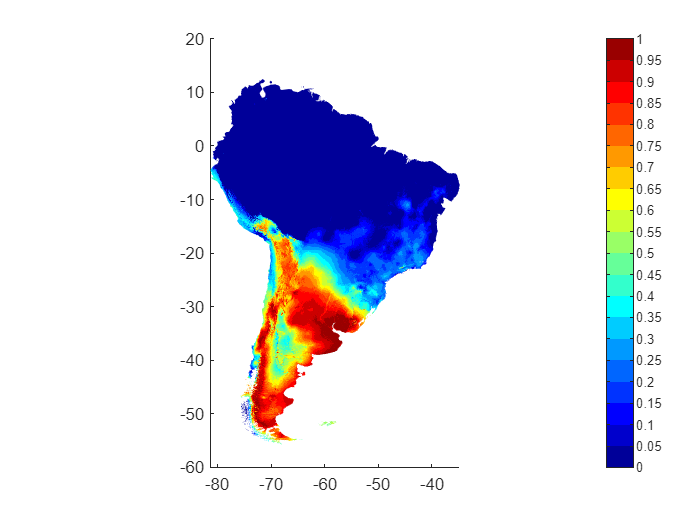

MapInfo = NicheGeneration(Layers, InfoInitialPoint, 0.5, true);

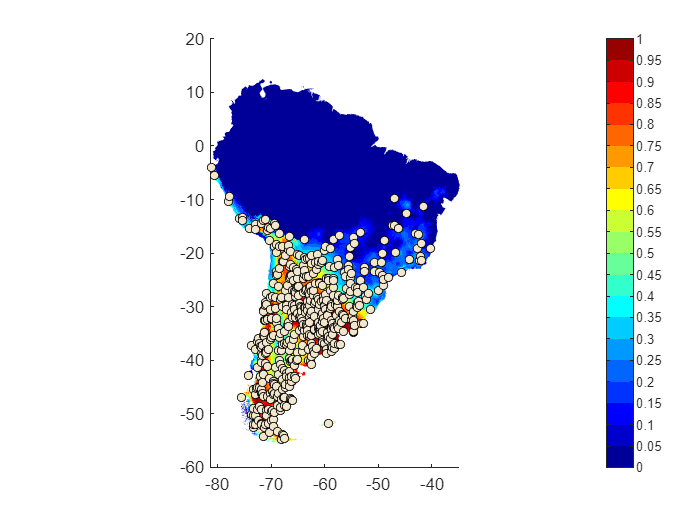

T = 494×22 table
    Name      LONG        LAT       bio1       bio2       bio3      bio4    bio5    bio6     bio7     bio8    bio9    bio10    bio11    bio12     bio13     bio14     bio15     bio16     bio17      bio18      bio19 
    _____    _______    _______    _______    ______    ________    ____    ____    ____    ______    ____    ____    _____    _____    ______

T = samplingVS(Layers, InfoInitialPoint, MapInfo, 500, -1, true, 'GenSP', true, true)

## Creación del objeto nicho (preprocesamiento de los datos)

El objeto se crea a partir de la tabla de observaciones de la especie, un método de normalización y los índices de las columnas de la tabla con información relevante para la modelación. Hay 3 métodos disponibles

- 1: Normalización con el intervalo [0 1] y removiendo outliers multivariados

- 2: Normalización estándar

- 3: Normalización robusta

niche=nicheData(T,3,4:22)

niche =   nicheData with properties:

       nData: [494×19 double]
        nObs: 494
       nVars: 19
        inds: [4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22]
    varNames: {'bio1'  'bio2'  'bio3'  'bio4'  'bio5'  'bio6'  'bio7'  'bio8'  'bio9'  'bio10'  'bio11'  'bio12'  'bio13'  'bio14'  'bio15'  'bio16'  'bio17'  'bio18'  'bio19'}
    clusters: []
      agents: []
     RAgents: []
       Graph: []


### Encontrar cluster de variables correlacionadas

Los clusters se crean a partir de un threshold para la correlación. Se considera que 2 variables pertenecen al mismo cluster si su índice de correlación supera el threshold en valor absoluto.

thr = 0.7;
niche=niche.aClus(thr)

niche =   nicheData with properties:

       nData: [494×19 double]
        nObs: 494
       nVars: 19
        inds: [4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22]
    varNames: {'bio1'  'bio2'  'bio3'  'bio4'  'bio5'  'bio6'  'bio7'  'bio8'  'bio9'  'bio10'  'bio11'  'bio12'  'bio13'  'bio14'  'bio15'  'bio16'  'bio17'  'bio18'  'bio19'}
    clusters: [7×19 logical]
      agents: [1 7 8 11 12 13 14]
     RAgents: [7×1 logical]
       Graph: []


### Crear los predictores finales

Con base en los representantes de cluster y los errores de regresión para cada representante. Es necesario correr esta línea de código para posteriormente generar la función de preprocesamiento de los datos

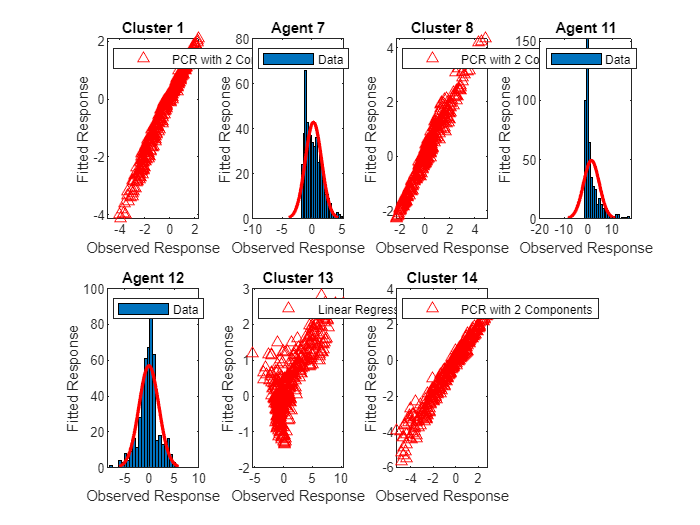

Cluster for Agent 1 is:
     1     2     3    15    16    18    19

Cluster for Agent 7 is:
     7

Cluster for Agent 8 is:
     4     5     8    10

Cluster for Agent 11 is:
    11

Cluster for Agent 12 is:
    12

Cluster for Agent 13 is:
    13    14

Cluster for Agent 14 is:
    13    14    17



niche=niche.regressor;

## Activación de la función de preprocesamiento

Se corre esta línea de código para activar la función de preprocesamiento. Dicha función tiene como dominio el conjunto de variables ambientales original y su rango son los representantes de cluster normalizados y sus respectivos errores normalizados. En general no tiene inversa.

niche=niche.setProcFun()

niche =   nicheData with properties:

       nData: [494×19 double]
        nObs: 494
       nVars: 19
        inds: [4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22]
    varNames: {'bio1'  'bio2'  'bio3'  'bio4'  'bio5'  'bio6'  'bio7'  'bio8'  'bio9'  'bio10'  'bio11'  'bio12'  'bio13'  'bio14'  'bio15'  'bio16'  'bio17'  'bio18'  'bio19'}
    clusters: [7×19 logical]
      agents: [1 7 8 11 12 13 14]
     RAgents: [7×1 logical]
       Graph: []


### Ejemplo de preprocesamiento de los datos

pData sería el input de los algoritmos de modelado de nicho

pData = niche.procFun(T{:,niche.inds})

ans =     1.5522    4.2526   -2.0072   -1.4490    0.2226    5.8477   -2.8179   -0.1763   -0.4189    1.7243    2.0370
   -2.7673    1.4064    0.2151   -1.2245    1.1684   10.4508   -4.8532    1.9481    0.5536    3.4468    2.7146
    0.3577    2.9078   -2.1505   -1.4490   -2.3171    5.6230   -3.5036    0.2149    0.2110    1.4462    2.8166
   -2.1028   -1.6617    2.7168   12.4490   -7.8836   -5.4339   -2.1161    2.0295   -2.3849   -3.5569   -3.5926
   -1.1295    3.5182    0.2007   -1.4286    0.3938    8.9847   -4.8805    1.6783    1.1377    2.7312    0.9313
   -0.8727    4.5951   -0.7599   -1.4490    0.3867    9.2439   -4.6233    1.4194    0.3914    2.9201    2.2304
   -2.0788    3.1791    0.4158   -1.3265    2.0977    9.3105   -4.4307    1.7262    2.1611    2.9999    0.9800
   -3.9209   -1.2959    1.4194    6.0816   -4.9616   -0.2796   -2.2061    1.2886   -1.2048   -1.0871    0.1578
   -0.8742    1.1363    2.0502   10.2653   -3.4025    2.3280   -2.9511   -0.2211    0.5356   -0.0104    0.